# **Actividad: Feature Extraction**

Carlos Enrique Lopez Jimenez A01283855 

Genaro Gallardo Bórquez A01382459 

Claudia Esmeralda González Castillo A01411506 

Jesús Eduardo Martínez Herrera A01283785 

Mario Veccio Castro Berrones A00826824

## Using LBP Features to Differentiate Images by Texture

Read images that contain different textures.

brickWall = imread('brickwall.jpg');
rotatedBrickWall = imread('brickwallRotado.jpg');
carpet = imread('carpeta.jpg');

graybrickWall = rgb2gray(brickWall);
grayrotatedBrickWall = rgb2gray(rotatedBrickWall);
graycarpet = rgb2gray(carpet);

Display the images.

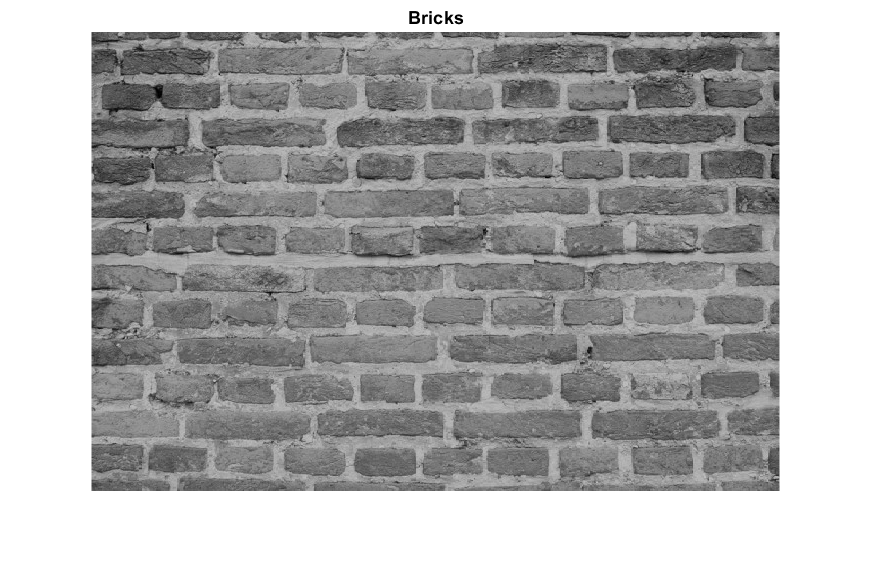

figure
imshow(brickWall)
title('Bricks')

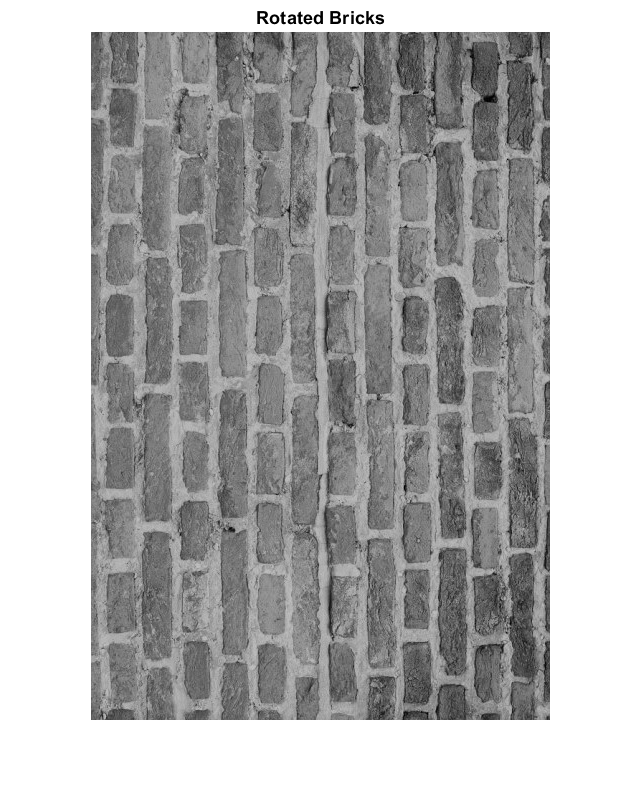


figure
imshow(rotatedBrickWall)
title('Rotated Bricks')

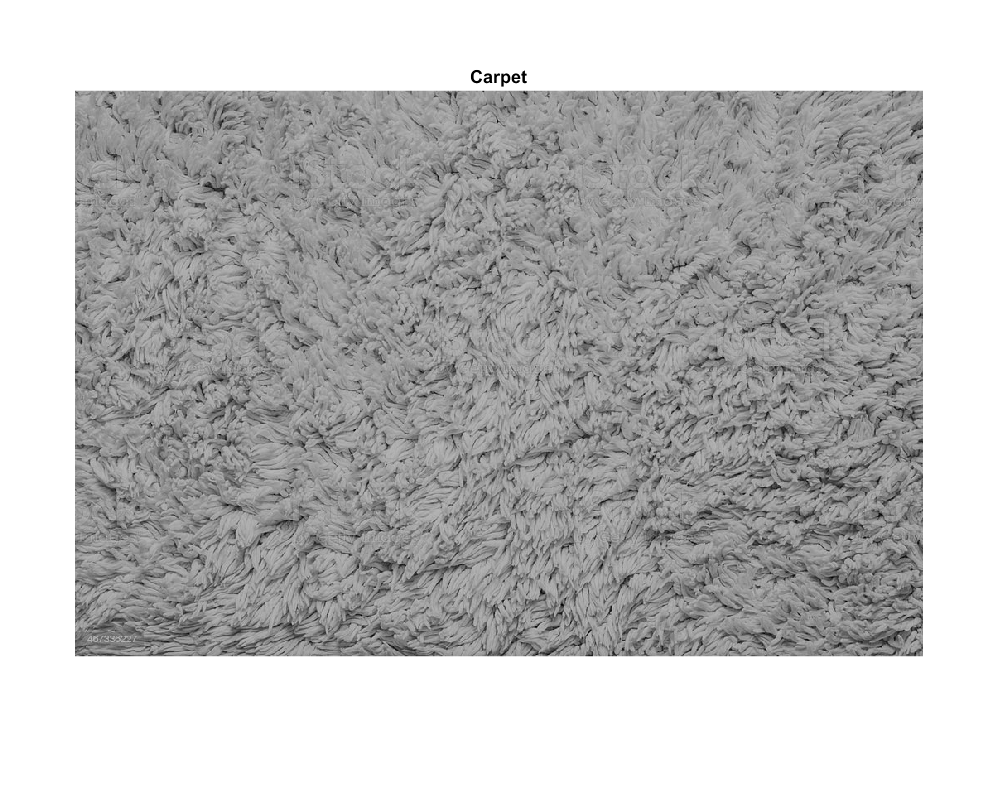


figure
imshow(carpet)
title('Carpet')

Extract LBP features from the images to encode their texture information.

lbpBricks1 = extractLBPFeatures(graybrickWall,'Upright',false);
lbpBricks2 = extractLBPFeatures(grayrotatedBrickWall,'Upright',false);
lbpCarpet = extractLBPFeatures(graycarpet,'Upright',false);

Gauge the similarity between the LBP features by computing the squared error between them.

brickVsBrick = (lbpBricks1 - lbpBricks2).^2;
brickVsCarpet = (lbpBricks1 - lbpCarpet).^2;

Visualize the squared error to compare bricks versus bricks and bricks versus carpet. The squared error is smaller when images have similar texture.

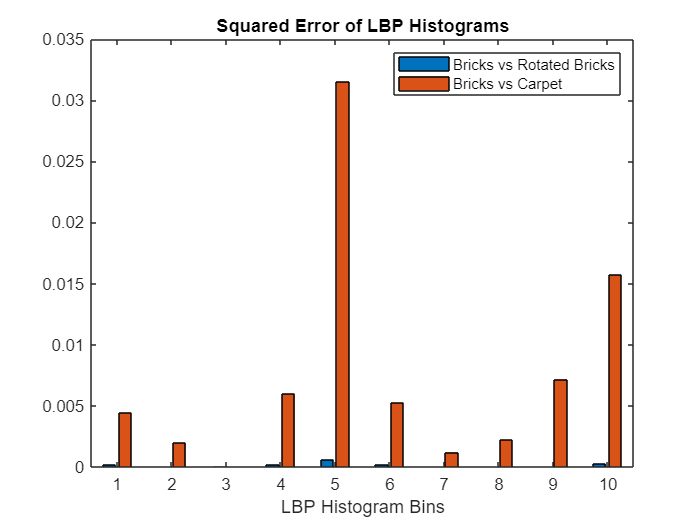

figure
bar([brickVsBrick; brickVsCarpet]','grouped')
title('Squared Error of LBP Histograms')
xlabel('LBP Histogram Bins')
legend('Bricks vs Rotated Bricks','Bricks vs Carpet')

*Copyright 2015 The MathWorks, Inc.*

## Create Gray-Level Co-occurrence Matrix for Grayscale Image

Read a grayscale image into the workspace.

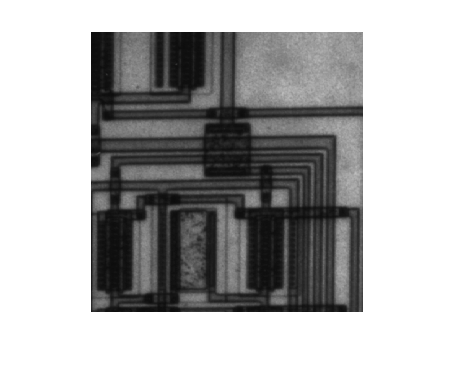

I = imread('circuit.tif');
imshow(I)

Calculate the gray-level co-occurrence matrix (GLCM) for the grayscale image. By default, `graycomatrix` calculates the GLCM based on horizontal proximity of the pixels: [0 1]. That is the pixel next to the pixel of interest on the same row. This example specifies a different offset: two rows apart on the same column.

glcm = graycomatrix(I,'Offset',[2 0])

glcm =        14205        2107         126           0           0           0           0           0
        2242       14052        3555         400           0           0           0           0
         191        3579        7341        1505          37           0           0           0
           0         683        1446        7184        1368           0           0           0
           0           7         116        1502       10256        1124           0           0
           0           0           0           2        1153        1435           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0


*Copyright 2012 The MathWorks, Inc.*